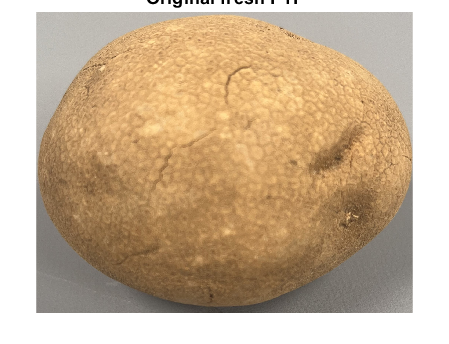

close all
clear all
clc

A = imread('fresh_P1F.jpg');
figure,imshow(A);title('Original fresh P1F');

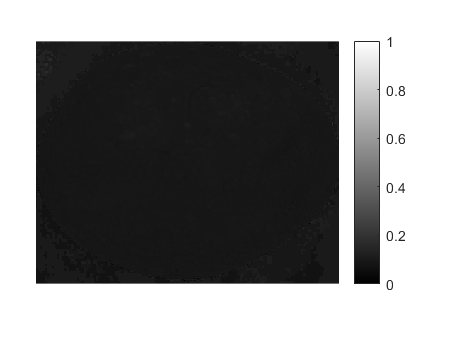

HSV = rgb2hsv(A);
H = HSV(:,:,1); %Hue
figure,imshow(H);colorbar;

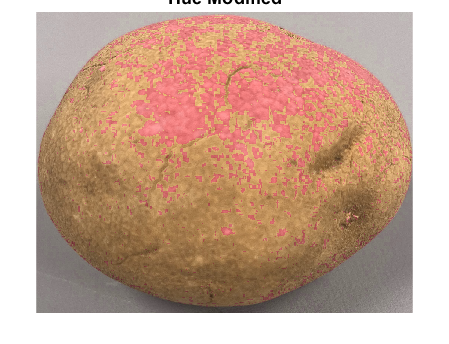


H( H > mean2(H) ) = 1;
HSV(:,:,1) = H;

C = hsv2rgb(HSV);
figure,imshow(C);title('Hue Modified');

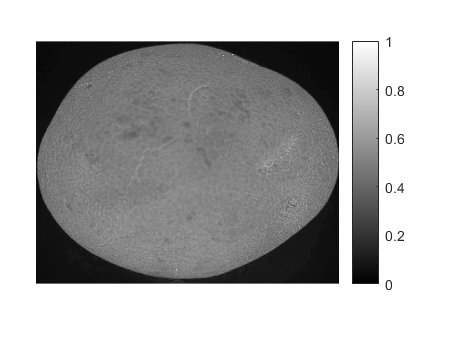

HSV = rgb2hsv(A);
S = HSV(:,:,2); %Saturation
figure,imshow(S);colorbar;


new = hsv2rgb(S)

Error using hsv2rgb
MAP must be a Mx3 array.

figure,imshow(new)